syms x y a b
assume([x y a b], "real")

% Construct quadratic objective
f = (x-a)^2 + (y-b)^2;

% Construct nonlinear (geometric) equality constraint
g = exp(x) - y;
%g = x*y - 1/(x*y);
%g = x^2 + y^2 - 4;

struct_vals = struct();
struct_vals.a = 1;
struct_vals.b = 0;

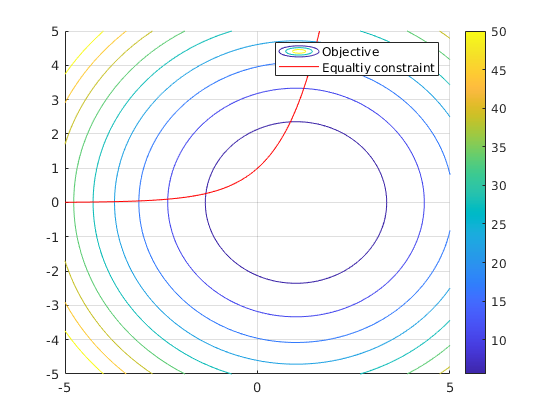

figure()
hold on

fcontour(subs(f, struct_vals), levellist=linspace(0, 50, 10))
fimplicit(g == 0, color='r')
legend("Objective", "Equaltiy constraint")
grid on
colorbar

q = [x y];
syms lambda
assume(lambda, "real")

L = f - lambda*g

$$L = \lambda \,\left(y-{\mathrm{e}}^{x}\right)+{\left(a-x\right)}^{2}+{\left(b-y\right)}^{2}$$

grad_L = gradient(L, [q, lambda])

$$grad\_L = \left(\begin{array}{c} 2\,x-2\,a-\lambda \,{\mathrm{e}}^{x}\\ \lambda -2\,b+2\,y\\ y-{\mathrm{e}}^{x} \end{array}\right)$$

soln = vpasolve(subs(grad_L, struct_vals) == zeros(size(grad_L)), [q, lambda], repmat([-inf, inf], 3, 1));

eval([soln.x, soln.y])

ans =      0     1


eval(subs(subs(f, struct_vals), soln))

ans = 2

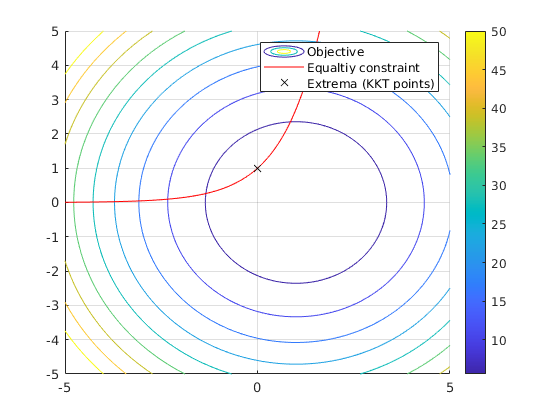

figure()
hold on

fcontour(subs(f, struct_vals), levellist=linspace(0, 50, 10))
fimplicit(g == 0, color='r')
plot(soln.x, soln.y, 'kx')
legend("Objective", "Equaltiy constraint", "Extrema (KKT points)")
grid on
colorbar

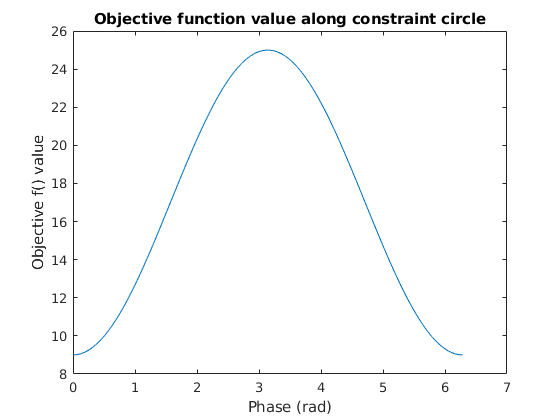

f_eval_f = @(x, y) eval(subs(subs(f, struct_vals), struct("x", x, "y", y)));

t = linspace(0, 2*pi);
circle_points = [4*cos(t); 4*sin(t)];
f_val_circle = f_eval_f(circle_points(1, :), circle_points(2, :));

figure()
plot(t, f_val_circle)
title("Objective function value along constraint circle")
xlabel("Phase (rad)")
ylabel("Objective f() value")

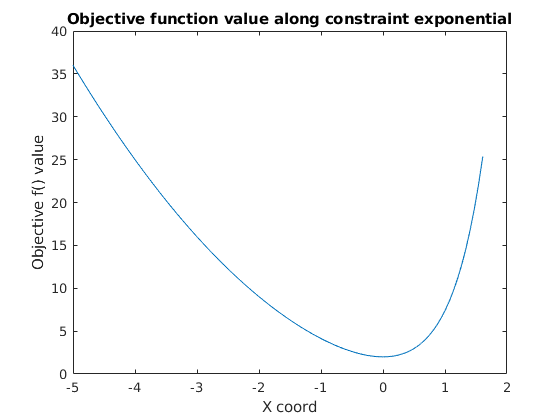

x_vals = linspace(-5, log(5), 100);
y_vals = exp(x_vals);
f_val_exp = f_eval_f(x_vals, y_vals);

figure()
plot(x_vals, f_val_exp)
title("Objective function value along constraint exponential")
xlabel("X coord")
ylabel("Objective f() value")